Bekannte Größen

delta_x = 2.0e-6;
a = ones(100, 1);
A1 = diag(-2*a);
a = ones(99, 1);
A2 = diag(a,1);
A3 = diag(a, -1);
A_l = 1/(delta_x^2) * (A1 + A2 + A3);
x = linspace(0, 20e-6, 100)

x = 1.0e-04 *

         0    0.0020    0.0040    0.0061    0.0081    0.0101    0.0121    0.0141    0.0162    0.0182    0.0202    0.0222    0.0242    0.0263    0.0283    0.0303    0.0323    0.0343    0.0364    0.0384    0.0404    0.0424    0.0444    0.0465    0.0485    0.0505    0.0525    0.0545    0.0566    0.0586    0.0606    0.0626    0.0646    0.0667    0.0687    0.0707    0.0727    0.0747    0.0768    0.0788    0.0808    0.0828    0.0848    0.0869    0.0889    0.0909    0.0929    0.0949    0.0970    0.0990


n = ones(100,1) * 1.45;
% n(40:60) = 1.46; % ein zenraler WL
% 2 nahe WL -> starke Koppelung
n(25:45) = 1.47

n =     1.4500
    1.4500
    1.4500
    1.4500
    1.4500
    1.4500
    1.4500
    1.4500
    1.4500
    1.4500


n(55:75) = 1.47

n =     1.4500
    1.4500
    1.4500
    1.4500
    1.4500
    1.4500
    1.4500
    1.4500
    1.4500
    1.4500


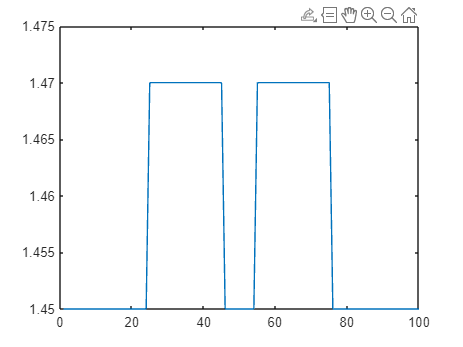

plot(n)

lambda = 1.55e-6;
k_0 = 2*pi / lambda;
A = A_l + k_0^2 * diag(n.^2)

A = 1.0e+13 *

    3.4049    0.0250         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0250    3.4049    0.0250         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

Lösung des Eigenwertproblems

ew = eig(A);
[V,D] = eig(A)

V =          0   -0.0350         0    0.0695   -0.0000         0   -0.1029         0    0.1347         0   -0.0000   -0.1644         0    0.1916         0   -0.2159   -0.0000         0    0.2368         0   -0.2541         0    0.0000    0.2674         0    0.2766    0.0000   -0.2815    0.0000    0.0000   -0.2820   -0.0000   -0.2781    0.0000    0.0000   -0.2699   -0.0000    0.2574   -0.0000   -0.2408    0.0000    0.0000   -0.2203   -0.0000    0.1963    0.0000    0.0000   -0.1691    0.0000    0.1390
         0    0.0695         0   -0.1346    0.0000         0    0.1915         0   -0.2366         0    0.0000    0.2670         0   -0.2810         0    0.2776    0.0000         0   -0.2569         0    0.2204         0   -0.0000   -0.1701         0   -0.1092   -0.0000    0.0414   -0.0000   -0.0000   -0.0292   -0.0000   -0.0980    0.0000    0.0000   -0.1608   -0.0000    0.2138   -0.0000   -0.2534    0.0000    0.0000   -0.2771   -0.0000    0.2834    0.0000    0.0000   -0.2716    0.0000    0

D = 1.0e+13 *

    3.3552         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    3.3553         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

n_eff = sqrt(ew / k_0^2)

n_eff =     1.4289
    1.4289
    1.4292
    1.4292
    1.4293
    1.4295
    1.4296
    1.4301
    1.4302
    1.4307


beta = sqrt(ew)

beta = 1.0e+06 *

    5.7924
    5.7925
    5.7934
    5.7935
    5.7941
    5.7949
    5.7951
    5.7970
    5.7974
    5.7996


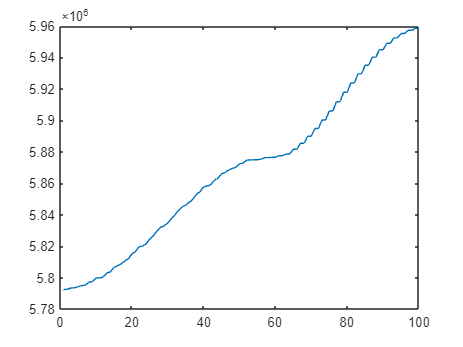

plot(beta)

Darstellen der Wellen

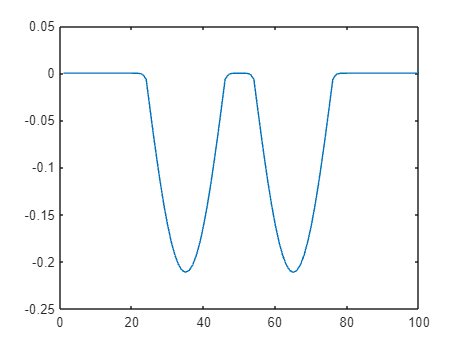

plot(V(:,100))

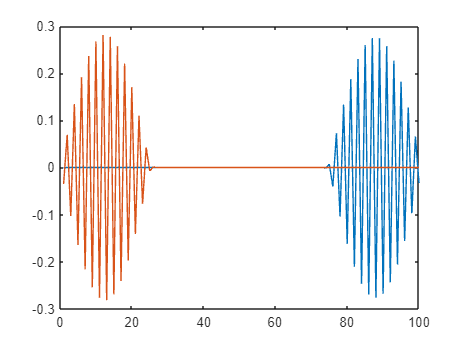

plot(V(:,1:2))

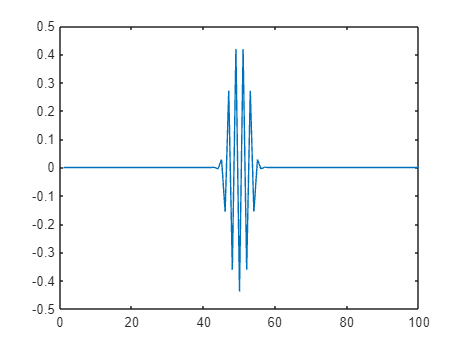

plot(V(:,5))

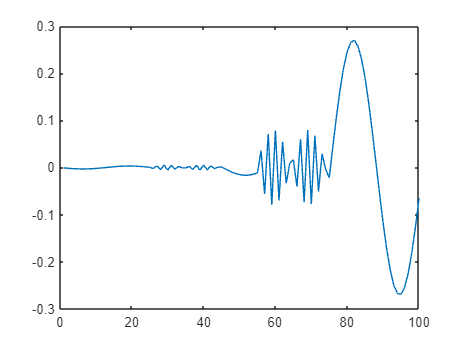

plot(V(:,60))

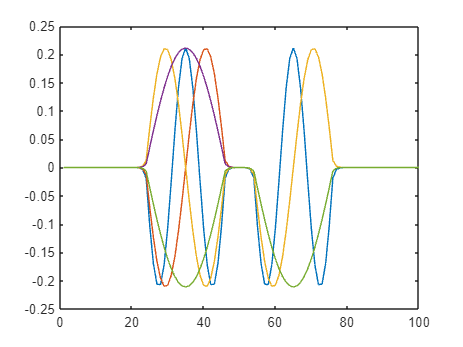

plot(V(:,96:100))

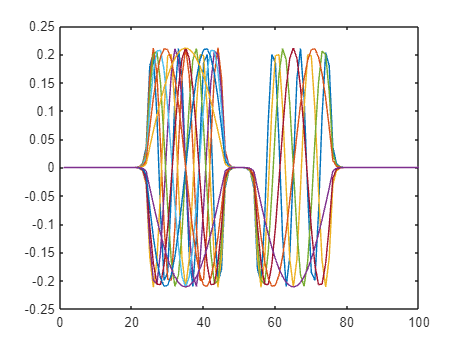

plot(V(:,90:100))

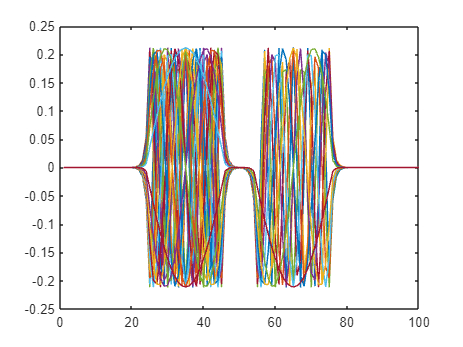

plot(V(:,80:100))

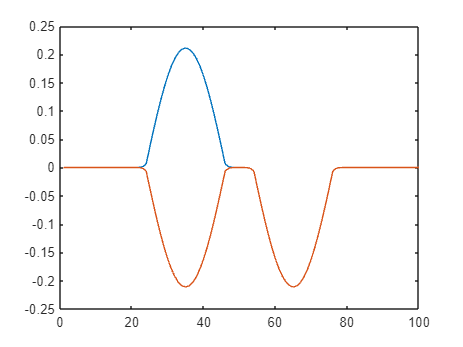

plot(V(:,99:100))


n_diff = n_eff(100) - n_eff(99)

n_diff = 4.4231e-12

n_eff < 1,